# 用全局优化工具箱ga算最小值

## MATLAB最带案例

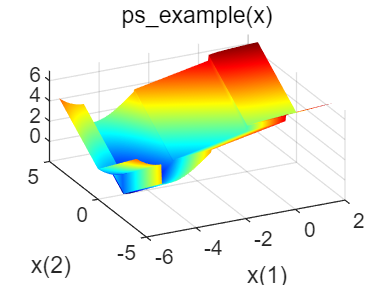

clear;
xi = linspace(-6,2,300);
yi = linspace(-4,4,300);
[X,Y] = meshgrid(xi,yi);
Z = ps_example([X(:),Y(:)]);
Z = reshape(Z,size(X));
surf(X,Y,Z,'MeshStyle','none')
colormap 'jet'
view(-26,43)
xlabel('x(1)')
ylabel('x(2)')
title('ps\_example(x)')

rng default % For reproducibility
x1 = ga(@ps_example,2)

lb = [1 -3];
ub = [6 8];
x2 = ga(@ps_example,2,[],[],[],[],lb,ub)

opt = optimoptions("ga",)
